# Spreading the butter to solve the diffusion equation

We're going to simulate diffusion of N0 molecules, starting in the middle of an *E. coli* cell. First, let's define the model parameters.

N0=100;             %number of molecules
D=10;               %diffusion constant in um^2/s
L=2;                %length of the cell in um
TotalTime=1E-3;     %in s (this means 1(10)^-3)

The simulation parameters are

dx=0.01;            %in um
M=L/dx;             %number of imaginary boxes in the E. coli cell
k=D/(dx^2);         %jump rate of a single molecule
dt=(1/k)/10;        %time step in s

Now we need to define the matrix we'll use to keep track of the molecules as well as the initial condition. The matrix N we'll use has TotalTime/dt rows (number of time points) and M columns (number of imaginary boxes).

First, we create a matrix of this size that is full of zeros. To do this, let's learn about assigning values to a range within a vector.

a=[2,5,7,8,1,3]

a =      2     5     7     8     1     3


a(2:5)=10

a =      2    10    10    10    10     3


I can do this in matrices as well:

c(1:3,1:4)=pi

c =     3.1416    3.1416    3.1416    3.1416
    3.1416    3.1416    3.1416    3.1416
    3.1416    3.1416    3.1416    3.1416


Now let's use this trick to initialize the N matrix

N(1:TotalTime/dt,1:M)=0;

I have the N matrix. Before I run the simulation I need to "seed it" using the initial condiiton.

N(1, M/2)=N0;

We're ready to run the simulation. I'm going to need two for-loops, one that goes over time and one that goes over the box number. For the latter for-loop, I need to be careful about box 1 and box M.

%for loop for time
for j=2:TotalTime/dt
    %for-loop for boxes 2 through M-1
    for i=2:M-1
       N(j, i)=N(j-1,i)+N(j-1,i+1)*k*dt...
           +N(j-1, i-1)*k*dt-2*N(j-1,i)*k*dt;%three dots=corrects the tine
    end
    N(j, 1) = N(j-1,1)+N(j-1,2)*k*dt-N(j-1,1)*k*dt; %box 1
    N(j, M)=N(j-1,M)+N(j-1,M-1)*k*dt-N(j-1,M)*k*dt; %box M
end

%row position j (time)
%column position i (box #)
%initial plus molec from right box

Plot the results using `bar3`.

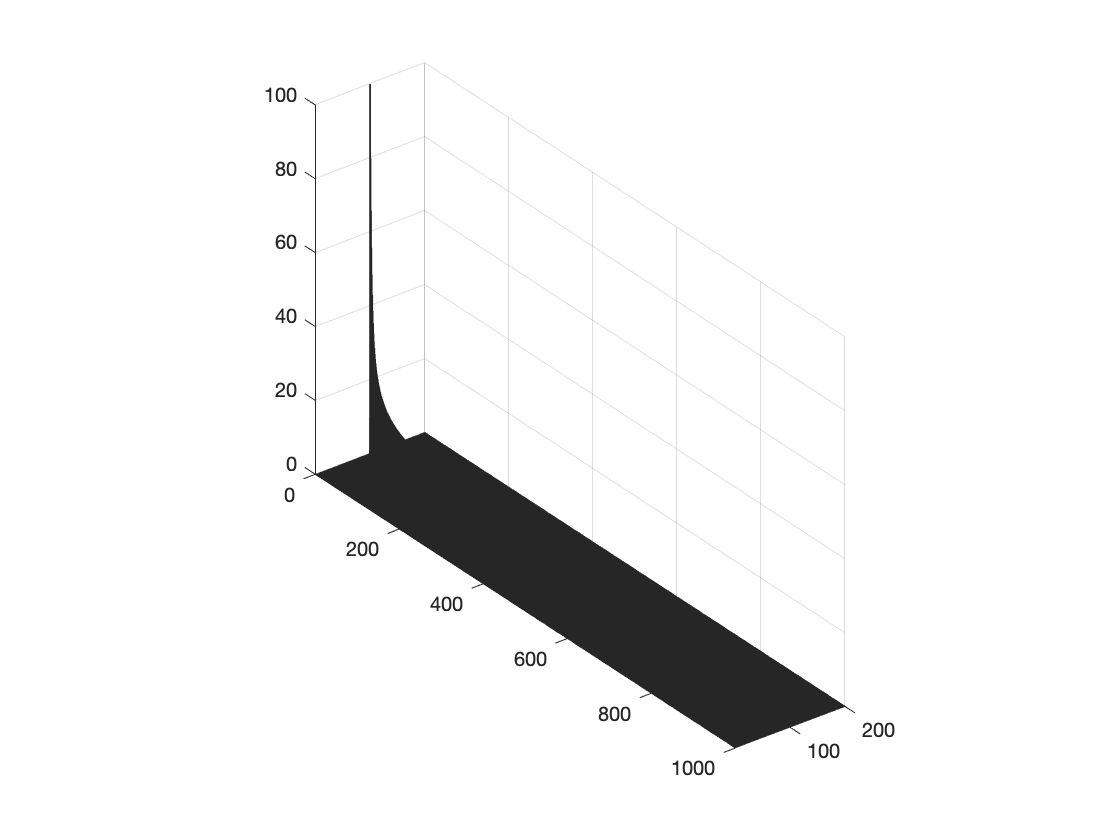

bar3(N);

%bar3(N(1:50:end),:)

Start at one:jump every 50:until the end of rows, and do all columns ":".

We'll also zoom in along the x axis between box 75 and 125 using the function `xlim`.

%xlim([75 125])
%ylim([0 5])

Finally, let's plot the distribution at different time points. To do this, I create a vector that keeps track of the box number.

Box=1:M;

Now plot the profile at the 100th time point. This means grabbing all columns along the 100th row of N. Let's also compare it to the distribution at the 400th time point.

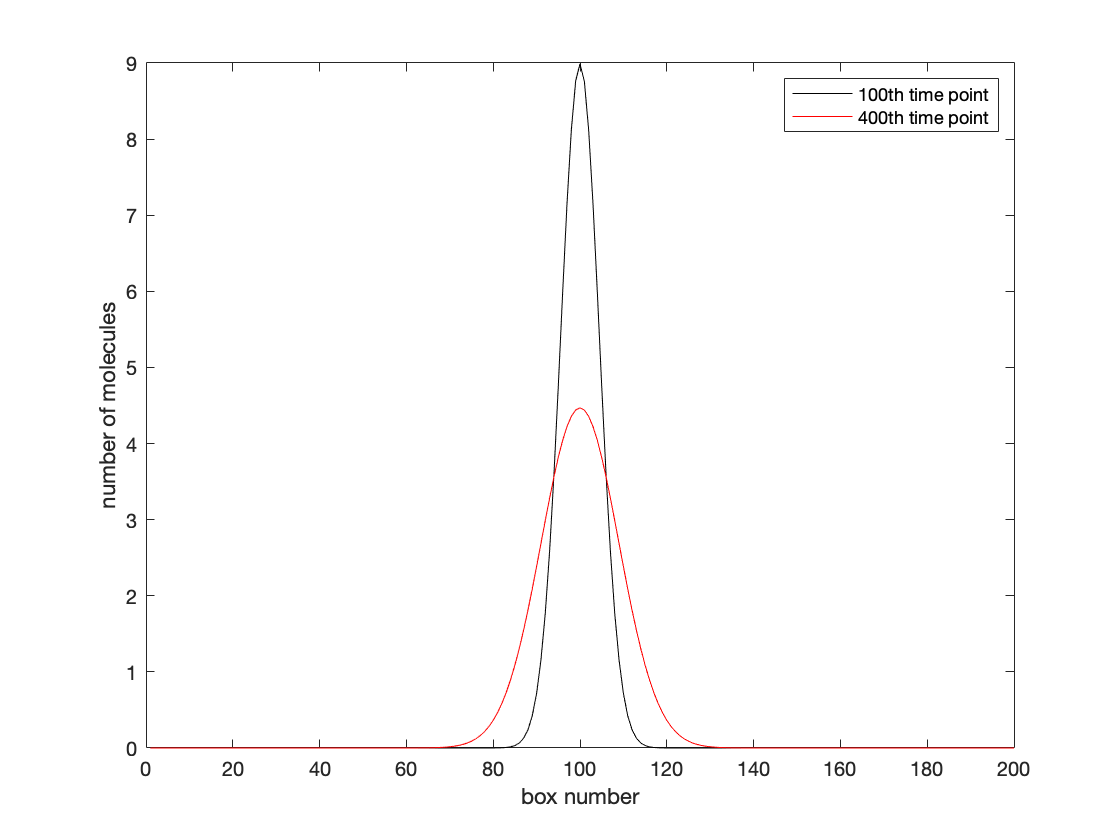

plot(Box, N(100,:), '-k')
hold on
plot(Box, N(400,:), '-r')
hold off
xlabel('box number')
ylabel('number of molecules')
legend('100th time point', '400th time point')